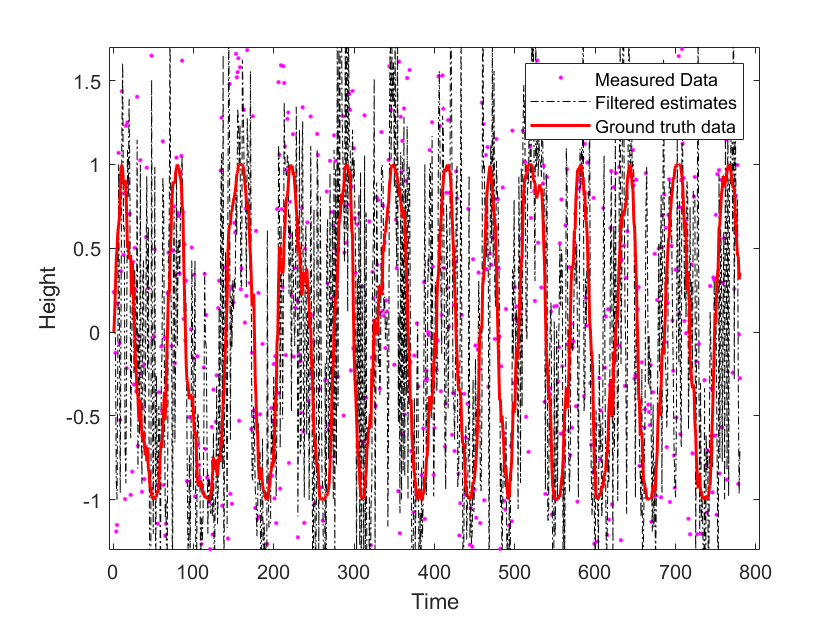

% This Program is written by Mayuresh Bhosale that depicts Extended Kalman
% Filter applied on a sinusoidal data

clc
clear all
close all
%1-D Data & Plot
Adata = importdata('sin-data.txt');
xaxis = 1:height(Adata);



% State variable matrix
X_t = [0; 0; 0];
% State transition equations/matrix
S_t = [1 0 0; 0 1 0; 0 0 1];
%Measurement variable
Y_t = Adata(1,2);

%Jacobian matrices
% derrivative of State transition equations wrt State variables
df_dx = [1 1 0;
         0 1 0;
         0.1*(cos(0.1*X_t(1))) 0 0];
% derrivative of State transition equations wrt Dyn noise
df_da = [0 0 0;
         0 1 0;
         0 0 0];
% derrivative of observation equations wrt State variables
dg_dx = [0 0 1];
%derrivative of observation equations wrt measurement noise
dg_dn = [1];

%Dynamic noise covariance
Q = [0 0 0;
     0 100 0;
     0 0 0];
%Measurement Noise Covariance
R = [1.2];
plotx = [];
Error = [];
for i = 1:length(Adata)
    % Predict next state
    X_t_t1 = [X_t(1)+X_t(2); X_t(2); sin(0.1*(X_t(1)))];
    %Predict next state covariance
    df_dx(3,1) = 0.1*cos(0.1*(X_t(1)));
    S_t_t1 = df_dx*S_t*(df_dx') + df_da*Q*(df_da');
    %Obtain measurement
    Y_t = [Adata(i,2)];
    %Caculate Kalman Gain
    K = S_t_t1*(dg_dx')*((dg_dx*S_t_t1*(dg_dx'))+(dg_dn*R*(dg_dn')))^(-1);
    %Update State
    X_t = X_t_t1 + K*(Y_t - (sin(0.1*(X_t(1)))));
    %Update state covariance
    S_t = (eye(3) - (K*dg_dx))*S_t_t1;
    plotx(i) = X_t(3);
    Error = sum(abs(X_t(3)-Adata(i,1)));
end

% t1 = tiledlayout(1,1);
% nexttile
% % plot(xaxis, Adata(:,2));
% % hold on
% plot(xaxis, Adata(:,1),"LineWidth",1.5,"Color",'k',"LineStyle","-");
% hold on
% plot(xaxis, Adata(:,2),"LineWidth",0.5,"Color",'k',"LineStyle","--");
% hold off
% ylabel('Height')
% xlabel('Time')
% legend('Ground truth data','Measured data')
% exportgraphics(t1,'Raw_data.eps')

% t2 = tiledlayout(1,1);
% nexttile
% % plot(xaxis, Adata(:,2));
% % hold on
% plot(xaxis, Adata(:,2),'k.');
% hold on
% plot(xaxis,plotx,"LineWidth",1.5,"Color",'k',"LineStyle","-.");
% plot(xaxis, Adata(:,1),"LineWidth",0.8,"Color",'k',"LineStyle","-");
% ylabel('Height')
% xlabel('Time')
% legend('Measured Data','Filtered estimates','Ground truth data')
% ylim([-1.3 1.7]);
% xlim([-5 805]);
% exportgraphics(t2,'Filter1.eps')


t2 = tiledlayout(1,1);
nexttile
% plot(xaxis, Adata(:,2));
% hold on
plot(xaxis, Adata(:,2),'m.');
hold on
plot(xaxis,plotx,"LineWidth",0.5,"Color",'k',"LineStyle","-.");
plot(xaxis, Adata(:,1),"LineWidth",1.5,"Color",'r',"LineStyle","-");
ylabel('Height')
xlabel('Time')
legend('Measured Data','Filtered estimates','Ground truth data')
ylim([-1.3 1.7]);
xlim([-5 805]);
exportgraphics(t2,'Filter3.eps')